# Frequency Domain Equalization

In this activity, you'll simulate an OFDM system, which includes a cyclic prefix and a frequency domain equalizer.

As with the IFFT, the OFDM modulator sends one 16-QAM symbol on each subcarrier. It then adds a cyclic prefix to create a single OFDM symbol, which is sent over the channel. In the receiver, the OFDM demodulator removes the cyclic prefix and performs an FFT. You then equalize the output in the frequency domain via division.

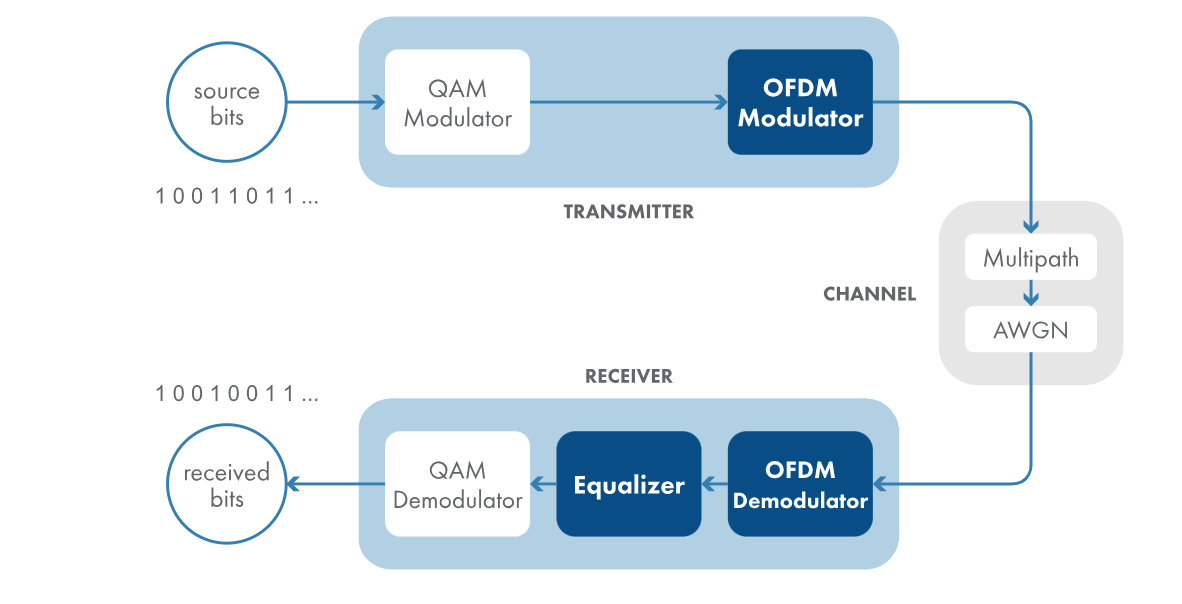

This code sets the simulation parameters.

modOrder = 16;  % for 16-QAM
bitsPerSymbol = log2(modOrder)  % modOrder = 2^bitsPerSymbol

bitsPerSymbol = 4


mpChan = [0.8; zeros(7,1); -0.5; zeros(7,1); 0.34];  % multipath channel
SNR = 15   % dB, signal-to-noise ratio of AWGN

SNR = 15

Background

**When designing a practical OFDM system, the number of subcarriers (the FFT size) is an important design parameter.**

The simulation in this activity is designed around the number of subcarriers—***one 16-QAM symbol is assigned to each subcarrier, creating a single OFDM symbol***. The number of source bits to generate is calculated by multiplying the number of subcarriers by the bits per 16-QAM symbol.

**TASK**

Define the number of subcarriers to be 8192 and store it in the variable `numCarr`. Then calculate the number of source bits to generate and store it in the variable `numBits`.

numCarr = 8192;
numBits = numCarr*bitsPerSymbol

numBits = 32768

**Task 2**

After setting the number of source bits, the script creates the source bit sequence and modulates it using 16-QAM.

The next step is to perform OFDM modulation, including a cyclic prefix.

The `ofdmmod` and `ofdmdemod` functions manage the cyclic prefix for you. All you have to do is specify the length of the cyclic prefix.

**The cyclic prefix must be at least as long as the impulse response of the channel**. But, it should also be reasonably short because it contains duplicate data that will be discarded. In this simulation, the multipath channel impulse response length is 17, so use a value slightly larger than that for the cyclic prefix length.

**TASK**

Define the cyclic prefix length to be 32 and store it in the variable `cycPrefLen`.

cycPrefLen =32;

Task 3

Use the `ofdmmod` function to perform OFDM modulation, specifying the number of subcarriers and the cyclic prefix length.

`sigOut` `=` `ofdmmod``(``sig``,``nCarr``,``cpLen``)`

**TASK**

Perform OFDM modulation on the signal `qamModOut`. Specify the number of subcarriers as `numCarr` and the cyclic prefix length as `cycPrefLen`.

Name the output signal `ofdmModOut`.

ofdmModOut = ofdmmod(qamModOut,numCarr,cycPrefLen);


Channel: multipath channel and AWGN


mpChanOut = filter(mpChan,1,ofdmModOut);
chanOut = awgn(mpChanOut,SNR,"measured");


Task 4

Next, the OFDM modulated signal is sent over the channel to the receiver.

In the receiver, perform OFDM demodulation using the `ofdmdemod` function, again specifying the number of subcarriers and the cyclic prefix length.

`sigOut` `=` `ofdmdemod``(``sig``,``nCarr``,``cpLen``)`

**TASK**

Perform OFDM demodulation on the signal `chanOut`. Specify the number of subcarriers as `numCarr` and the cyclic prefix length as `cycPrefLen`.

Name the output signal `ofdmDemodOut`.

Create a scatter plot of the OFDM demodulator output.

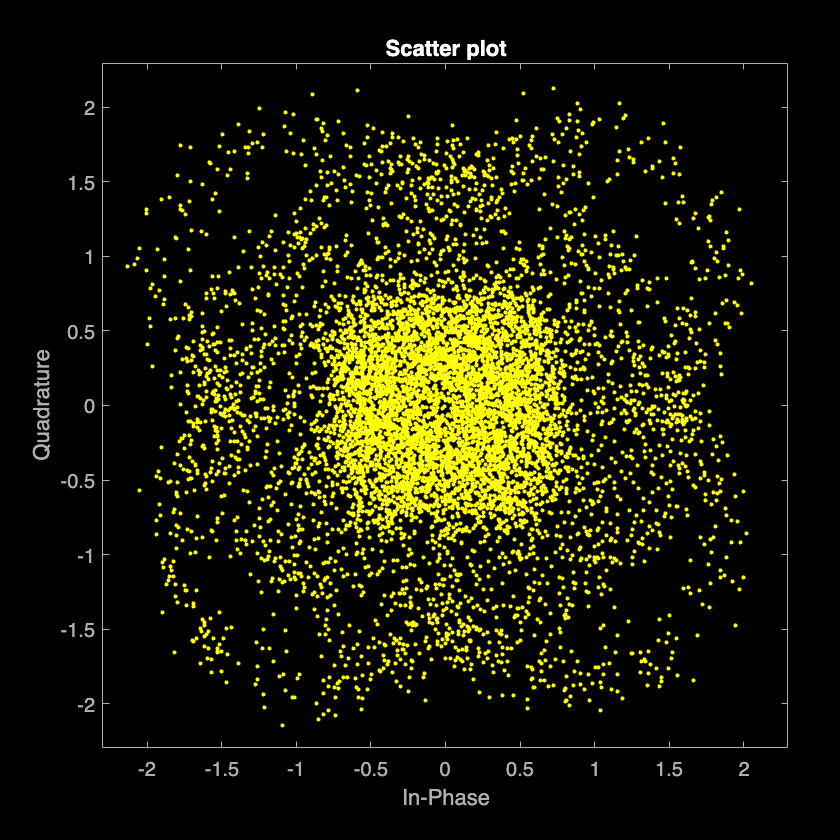

ofdmDemodOut = ofdmdemod(chanOut,numCarr,cycPrefLen);
scatterplot(ofdmDemodOut)

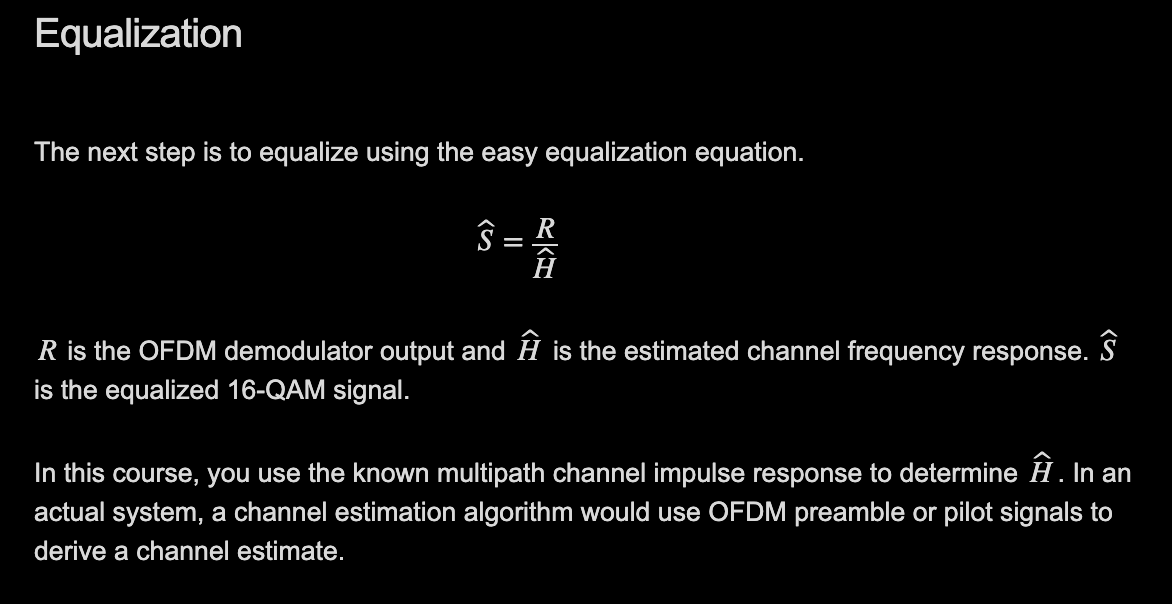

Task 5

Background

The equalization happens in the frequency domain, so you need to transform the channel impulse response using the `fft` function. **Set the FFT size by passing it as a second input.**

`fft``(``mpChan``,``numCarr``)`

*The *`fft`* function output starts with the zero-frequency component, but the *`ofdmdemod`* function specifies the zero-frequency component in the middle of the frequency range*. 

Use `fftshift` to shift the channel's spectrum so the zero-frequency component is in the center.

`fftshift``(``fft``(``mpChan``,``numCarr``))`

**TASK**

Transform the multipath channel impulse response `mpChan` to the frequency domain, with the zero-frequency component in the center of the frequency range. Name the result `mpChanFreq`.

mpChanFreq_estimate = fftshift(fft(mpChan,numCarr));

Task 6

Now you're ready to equalize the signal. To do so, divide it by the channel frequency response, element-wise.

Divide the two vectors element-wise using the `./` operator.

`x` `./` `y`

**TASK**

Equalize the signal `ofdmDemodOut` by dividing by `mpChanFreq`. Name the equalized signal `eqOut`.

Create a scatter plot of the equalized signal.

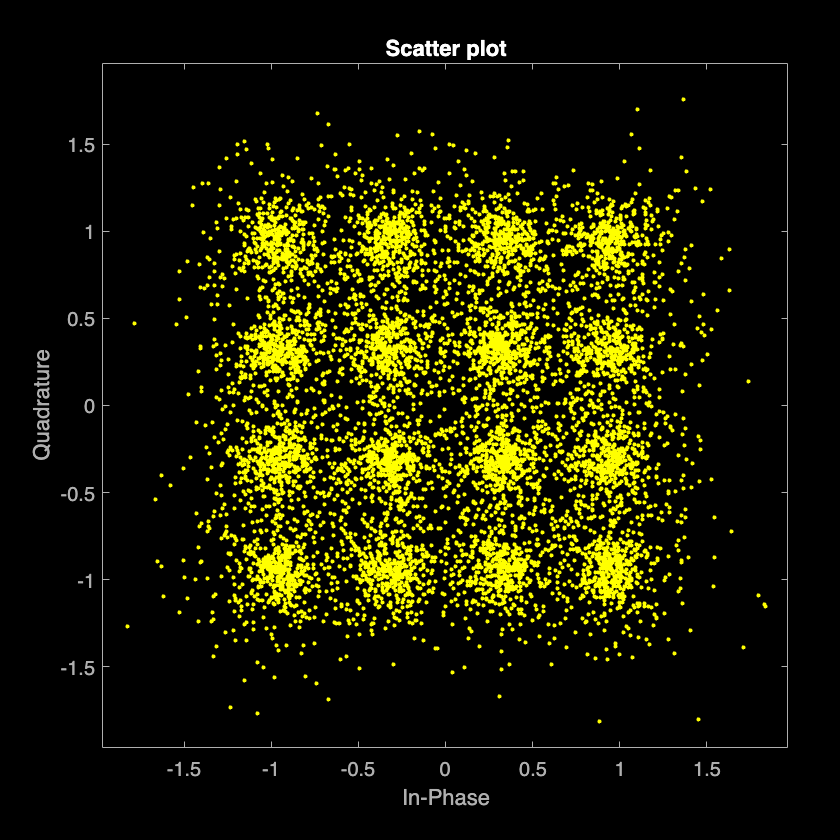

eqOut = ofdmDemodOut./mpChanFreq_estimate;
scatterplot(eqOut)

Demodulate back into bits, then calculate the BER.


qamDemodOut = qamdemod(eqOut,modOrder,"OutputType","bit","UnitAveragePower",true);
numBitErrors = nnz(srcBits~=qamDemodOut)

numBitErrors = 1281

BER = numBitErrors/numBits

BER = 0.0391

FURTHER PRACTICE

The scatter plot of the equalized signal much more closely resembles the desired constellation, and equalization has removed much of the multipath channel's effects.

The script demodulates the 16-QAM signal and calculates the bit error rate. The frequency domain equalizer greatly improves the link's performance, even in the presence of a multipath channel. To see the effect of the equalizer on just the multipath channel, try increasing `SNR` to 100 on line 5.

In this simulation, every subcarrier is a data subcarrier, but this isn't always the case. Some subcarriers are designated for other uses besides data. In the next activity, you'll use one such type of subcarrier — null subcarriers.